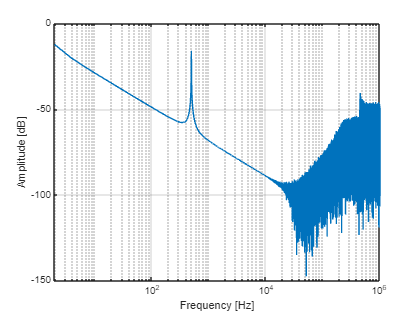

% SAC ISRO
% In this example, we are using a sample data from DSM for calculating
% SNDR. Make sure to keep "DSM_sample_data.mat" in the working directory. 
close all;
v1 = out.cout(:,2);
 % Remove the DC component from digital signal.

OSR = 1024; % Over-sampling Ratio
Fs = 2e3*OSR;
 NFFTv = 32768*32;
%  v1 = v1(end-NFFTv+1:end); % sampled @Fs
%  u_bipolar = 2*double(v1(:));
% 
%  carrier = ones(size(u_bipolar));
%  carrier(2:2:end) = -1; % period 2Ts, freq Fs/2
% 
% v1 = (u_bipolar .* carrier);
len = length(v1);
L = length(v1);
fv = Fs/2*linspace(0, 1, NFFTv / 2 + 1); % Frequency vector (Hz)
FS = 1.8;

% Compute PSD & plot
% Use this for no LEAKAGE :)

wind = hann(L, 'periodic');
fft_outv = fft(v1 .* wind, NFFTv);
% Ptot = (abs(fft_outv)).^2; % Power spectrum of the signal

% Normalise the peak of signal

Ptot = (abs(fft_outv)/(FS * sum(wind) * 1/4)).^2; % Power spectrum of the signal
fft_onesided = abs(Ptot(1:NFFTv/2+1));
figure;
semilogx(fv, 10*log10(fft_onesided)); 
xlim([0 Fs/2])
xlabel('Frequency [Hz]');
ylabel('Amplitude [dB]');
grid on;


% SNDR calculation
% Select appropriate signal bin for SNDR calculation
fin = (3117/(2*(pi))); 
k = round(fin * NFFTv / Fs) + 1;
sigbin = k-1:k+1;
% For signal power, integrate over input signal BW
sigpow = sum(fft_onesided(sigbin));
% For noise Power, integrate till nyquist frequency and subtract signal
% power.
npow = sum(fft_onesided(1:round(end/OSR))) - sigpow;

sndr = 10*log10(sigpow./npow); % Compute SNDR

